### Zadanie 1

A = 0.32345;
B = -0.78743;
C = 0.56532;
sign = 1; %0-unsigned value, 1-signed value % sign
prec_i = 1; %number of integer part bits (Nc) % one bit
prec_f = 10; %number of fractional part bits (Nu) % eight bits
word = 1 + prec_i + prec_f; % whole word

A_fix = fi(A, sign, word, prec_f)

A_fix = 14b

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 10

B_fix = fi(B, sign, word, prec_f)

B_fix = cda

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 10

C_fix = fi(C, sign, word, prec_f)

C_fix = 243

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 10


A_2 = double(A_fix);
B_2 = double(B_fix);
C_2 = double(C_fix);

acc_fix = A_fix + B_fix

acc_fix = 1e25

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 10

Y_fix = acc_fix * C_fix

Y_fix = 1fbcdaf

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 25
        FractionLength: 20


acc = A + B;
Y = acc * C;

error = [];
for i = 0:1:16
    i;
    word = 1 + 1 + i;
    A_fix = fi(A, sign, word, i);
    B_fix = fi(B, sign, word, i);
    C_fix = fi(C, sign, word, i);

    acc_fix = A_fix + B_fix;
    Y_fix = acc_fix * C_fix;
    
    error(i+1) = abs(Y - Y_fix);
end %if

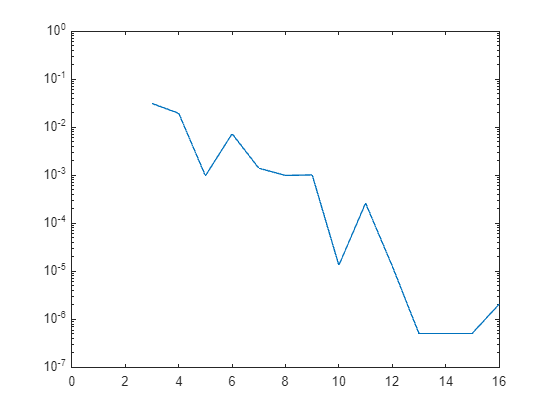

semilogy(0:1:16, error)

### Zadanie 2

format hex
A = -100.34;
B = 7.367;
C = -4.92;
D = 9.111;
E = -99.99;
F = 134.56;

sign = 1; %0-unsigned value, 1-signed value % sign

A_fix = fi(A, sign, 18, 8)

A_fix = 39ba9

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 8

B_fix = fi(B, sign, 8, 3)

B_fix = 3b

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 8
        FractionLength: 3

C_fix = fi(C, sign, 12, 7)

C_fix = d8a

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 7

D_fix = fi(A, sign, 8, 2)

D_fix = 80

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 8
        FractionLength: 2

E_fix = fi(E, sign, 14, 5)

E_fix = 3380

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 14
        FractionLength: 5

F_fix = fi(F, sign, 19, 9)

F_fix = 10d1f

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 19
        FractionLength: 9


Y = ((A_fix + B_fix)*C_fix) + ((D_fix + E_fix)*(E_fix + F_fix))

Y = 1ff7fbc8da

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 15


sumDE = D_fix + E_fix

sumDE = 6f80

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 15
        FractionLength: 5

sumEF = E_fix + F_fix

sumEF = 0451f

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 20
        FractionLength: 9


buf = (A_fix + B_fix)*C_fix

buf = 00e4c7da

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 31
        FractionLength: 15

buf1 = (D_fix + E_fix)*(E_fix + F_fix)

buf1 = 7fb8b8080

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 35
        FractionLength: 14

Y = buf + buf1

Y = 1ff7fbc8da

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 15

### Zadanie 3

format hex
A = [-5.67 21.348 9.111 -1.24 5.87 -4.123 9.34 0.12 -6.345 3.254]; %8c4u
A_fix = fi(A, 1, 13, 4)

A_fix = 1fa5   0156   0092   1fec   005e   1fbe   0095   0002   1f9a   0034

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 4

A_sum = fi(0, 1, 21, 4)

A_sum = 000000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4


for a = A_fix
    A_sum = accumpos(A_sum, a)
end

A_sum = 1fffa5

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

A_sum = 0000fb

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

A_sum = 00018d

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

A_sum = 000179

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

A_sum = 0001d7

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

A_sum = 000195

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

A_sum = 00022a

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

A_sum = 00022c

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

A_sum = 0001c6

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

A_sum = 0001fa

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4